numFich = 10

numFich = 10

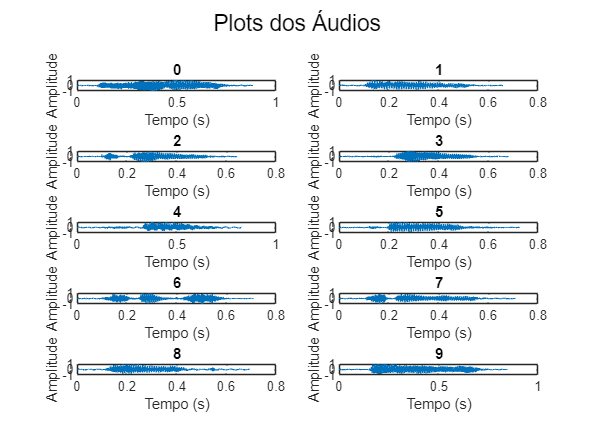

dados = ImportarDados(numFich);
Graficos(dados);


limiar = 0.1

limiar = 0.1000

tamanhoMaximo = 0;

for num = 1:numFich
    amplitude = dados{num}.amplitude;
    E = amplitude.^2;
    comeco = find(E > limiar * max(E), 1);
    amplitude = amplitude(comeco:end);

    if length(amplitude) > tamanhoMaximo
        tamanhoMaximo = length(amplitude);
    end

    dados{num}.energia = E;
    dados{num}.amplitude = amplitude;
end

for num = 1:numFich
    
    newAudio = dados{num}.amplitude;

    tamanhoSilencio = tamanhoMaximo - length(newAudio);

    if length(newAudio) < tamanhoMaximo
        silencio = zeros(tamanhoSilencio, 1);
        audioComFim = [newAudio;silencio];
        dados{num}.amplitude = audioComFim;
    end
   
end

for i = 1:numFich
    energia = dados{i}.energia;
    desvioPad = std(energia);
    media = mean(energia);
    total = sum(energia);
    dados{i}.desvio = desvioPad;
    dados{i}.media = media;
    dados{i}.total = total;
end


Foi escolhida a energia total, o desvio padrão da energia e a média da mesma, devido ao facto de ser possivel tirar boas conclusões através da análise da comparação entre as mesmas. Por exemplo, o número 6 apresenta uma média de energia baixa e um desvio padrão baixo logo, conclui-se que os valores não distam muito da média o que origina uma energia total baixa. Pela mesma ordem de pensamento, o número 9 apresenta uma média de energia elevada em comparação com os restantes números mas o seu desvio padrão continua a ser relativamente baixo resultanto numa energia total mais alta do que a dos restantes elementos.

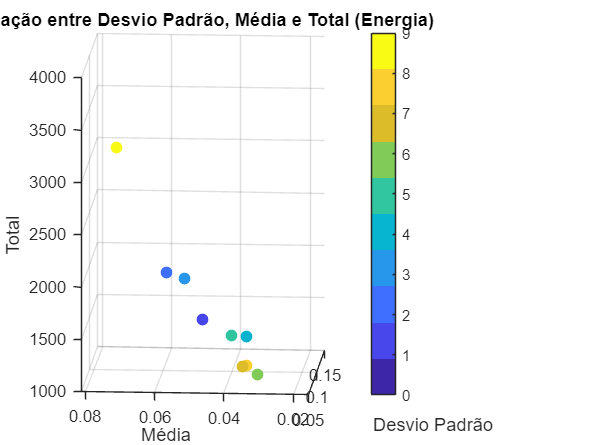


Grafico3D(dados,numFich);